clc;
clear all;

% syms e1 e1_dot e2 e2_dot C_y I_z v_xb v_yb L tau u_delta m
v_xb = 2.0

v_xb = 2

tau= 0.1

tau = 0.1000

L = 0.4

L = 0.4000

C_y = 100

C_y = 100

m = 11.5

m = 11.5000

I_z = 0.5

I_z = 0.5000

A = [[0, 1, 0, 0];
    [0, -C_y/(m*v_xb), C_y/m, 0];
    [0, 0, 0, 1];
    [0, 0, 0, (-L^2 * C_y)/(2*I_z*v_xb)]]

A =          0    1.0000         0         0
         0   -4.3478    8.6957         0
         0         0         0    1.0000
         0         0         0   -8.0000



B = [0, C_y/m, 0, (C_y*L)/(2*I_z)].'

B =          0
    8.6957
         0
   40.0000



C = [0, -v_xb, 0, (-L^2 * C_y)/(2*I_z*v_xb)]

C =          0   -2.0000         0   -8.0000


D = [0]

D = 0


R = [B, A*B, A^2 *B, A^3 * B];
[u, s, v] = svd(R, "econ")

u =     0.0240    0.1993   -0.9777   -0.0615
   -0.2352   -0.9513   -0.1989   -0.0121
    0.1205   -0.0288   -0.0652    0.9902
   -0.9642    0.2334    0.0161    0.1252


s = 1.0e+04 *

    2.1409         0         0         0
         0    0.0119         0         0
         0         0    0.0009         0
         0         0         0    0.0005


v =    -0.0019    0.0089   -0.1172    0.9931
    0.0151   -0.3203   -0.9410   -0.1081
   -0.1228    0.9395   -0.3164   -0.0460
    0.9923    0.1211   -0.0251   -0.0022


rank(R)

ans = 4

eig(A)

ans =          0
   -4.3478
         0
   -8.0000


% zeros(4,1)
% A_aug = [A, zeros(4,1);
%          C, 0]
% B_aug = [B; 0]
% 
% rank(ctrb(A_aug, B_aug))
% before = [v_xb, tau, L, C_y, m, I_z];
% after = [2.0, 0.1, 0.4, 100, 11.5, 0.5];
% 
% A = double(subs(A, before, after))

% First Pole Placement
sys = ss(A, B, C, D, 0.01)

sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0  -4.348   8.696       0
   x3       0       0       0       1
   x4       0       0       0      -8
 
  B = 
          u1
   x1      0
   x2  8.696
   x3      0
   x4     40
 
  C = 
       x1  x2  x3  x4
   y1   0  -2   0  -8
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.


eig(A)

ans =          0
   -4.3478
         0
   -8.0000


P = [-1, -2, -3, -4]

P =     -1    -2    -3    -4


K = place(A, B, P)

K =     0.0690    0.0118    0.2362   -0.0613



Acl = A-B*K

Acl =          0    1.0000         0         0
   -0.6000   -4.4507    6.6414    0.5328
         0         0         0    1.0000
   -2.7600   -0.4732   -9.4497   -5.5493


Ecl = eig(Acl)

Ecl =    -1.0000
   -2.0000
   -3.0000
   -4.0000


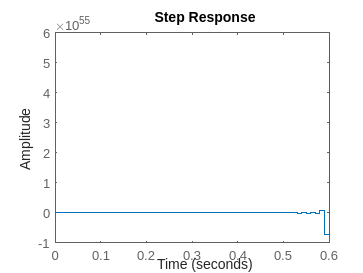

step(sys)

clc;
clear all;

v_xb = 2.0

v_xb = 2

tau= 0.1

tau = 0.1000

L = 0.4

L = 0.4000

C_y = 100

C_y = 100

m = 11.5

m = 11.5000

I_z = 0.5

I_z = 0.5000

A = [[0, 1, 0, 0];
    [0, -C_y/(m*v_xb), C_y/m, 0];
    [0, 0, 0, 1];
    [0, 0, 0, (-L^2 * C_y)/(2*I_z*v_xb)]]

A =          0    1.0000         0         0
         0   -4.3478    8.6957         0
         0         0         0    1.0000
         0         0         0   -8.0000



B = [0, C_y/m, 0, (C_y*L)/(2*I_z)].'

B =          0
    8.6957
         0
   40.0000



C = [0, -v_xb, 0, (-L^2 * C_y)/(2*I_z*v_xb)]

C =          0   -2.0000         0   -8.0000


D = [0]

D = 0


R = [B, A*B, A^2 *B, A^3 * B];

k = sym('k', [4 4])

$$k = \left(\begin{array}{cccc} k_{1,1} & k_{1,2} & k_{1,3} & k_{1,4}\\ k_{2,1} & k_{2,2} & k_{2,3} & k_{2,4}\\ k_{3,1} & k_{3,2} & k_{3,3} & k_{3,4}\\ k_{4,1} & k_{4,2} & k_{4,3} & k_{4,4} \end{array}\right)$$

e = sym('e', [4 1])

$$e = \left(\begin{array}{c} e_{1}\\ e_{2}\\ e_{3}\\ e_{4} \end{array}\right)$$

clc;
clear all;
syms e1 e1_dot e2 e2_dot C_y I_z v_xb v_yb L tau u_delta m
e_dot = [e1 e1_dot e2 e2_dot].'

$$e\_dot = \left(\begin{array}{c} e_{1}\\ e_{\dot{1}}\\ e_{2}\\ e_{\dot{2}} \end{array}\right)$$

A = [[0, 1, 0, 0];
    [0, -C_y/(m*v_xb), C_y/m, 0];
    [0, 0, 0, 1];
    [0, 0, 0, (-L^2 * C_y)/(2*I_z*v_xb)]]

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & -\frac{C_{y}}{m\,v_{\mathrm{xb}}} & \frac{C_{y}}{m} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & 0 & -\frac{C_{y}\,L^{2}}{2\,I_{z}\,v_{\mathrm{xb}}} \end{array}\right)$$

A*e_dot

$$ans = \left(\begin{array}{c} e_{\dot{1}}\\ \frac{C_{y}\,e_{2}}{m}-\frac{C_{y}\,e_{\dot{1}}}{m\,v_{\mathrm{xb}}}\\ e_{\dot{2}}\\ -\frac{C_{y}\,L^{2}\,e_{\dot{2}}}{2\,I_{z}\,v_{\mathrm{xb}}} \end{array}\right)$$